# Stiff ordinary differential equation

This script demonstrates how you can solve a stiff ordinary differential equation with a given initial condition in Matlab.

## Stiff differential equations

In mathematics, a [**stiff equation**](https://en.wikipedia.org/wiki/Stiff_equation) is a differential equation for which certain numerical methods for solving the equation are [numerically unstable](https://en.wikipedia.org/wiki/Numerical_stability), unless the step size is taken to be extremely small. It has proven difficult to formulate a precise definition of stiffness, but the main idea is that the equation includes some terms that can lead to rapid variation in the solution.

### Van der Pol oscillator

One example for stiff differential equations is the [Van der Pol oscillator](https://en.wikipedia.org/wiki/Van_der_Pol_oscillator) which has the following equation:


$$\frac{d^2x}{dt^2} - \mu(1 - x^2) \frac{dx}{dt} + x = 0$$


where $x$ is the position coordinate, which is a function of the time $t$, and $\mu$ is a scalar parameter. The Van der Pol oscillator is represented by a second-order differential equation; therefore, it has to be converted into a first-order differential equation system. 

Let $X(t)$ denote the state vector of the system containing the $x(t)$ displacement function is question and its $\frac{dx(t)}{dt}$ derivative as:

$X = \left[ \matrix{x(t) \cr \frac{dx(t)}{dt}} \right], \quad
\frac{dX}{dt} = \left[ \matrix{\frac{dx(t)}{dt} \cr \frac{d^2x(t)}{dt^2} } \right]$.

Then, the original second-order equation can be formulated as:


$$\frac{dX}{dt} = 
\left[ \matrix{X_2 \cr \mu(1 - X_1^2)X_2 - X_1} \right]$$


## Solving the Van der Pol equation

### Creating function handle

Creating a function handle for the generic Van der Pol oscillator:

vanDerPolFcnHandle = @(t, X, mu) vanDerPolEquation(t, X, mu);

Creating a function handle for a specific Van der Pol oscillator with given $\mu = 100$ parameter.

vanDerPol100FcnHandle = @(t, X) vanDerPolFcnHandle(t, X, 100);

### Initial conditions

timeSpan = [0, 300];
X0 = [2, 0];

### Solution

tic;
[timeVect1, XMat1] = ode45(vanDerPol100FcnHandle, timeSpan, X0);
elapsedTime = toc;
fprintf('The solution performed by ode45 lasted %gs in %d steps.\n', ...
    elapsedTime, length(timeVect1));

The solution performed by ode45 lasted 0.112373s in 67665 steps.



tic; 
[timeVect2, XMat2] = ode23s(vanDerPol100FcnHandle, timeSpan, X0);
elapsedTime = toc;
fprintf('The solution performed by ode23s lasted %gs in %d steps.\n', ...
    elapsedTime, length(timeVect2));

The solution performed by ode23s lasted 0.0412061s in 534 steps.


## Visualization

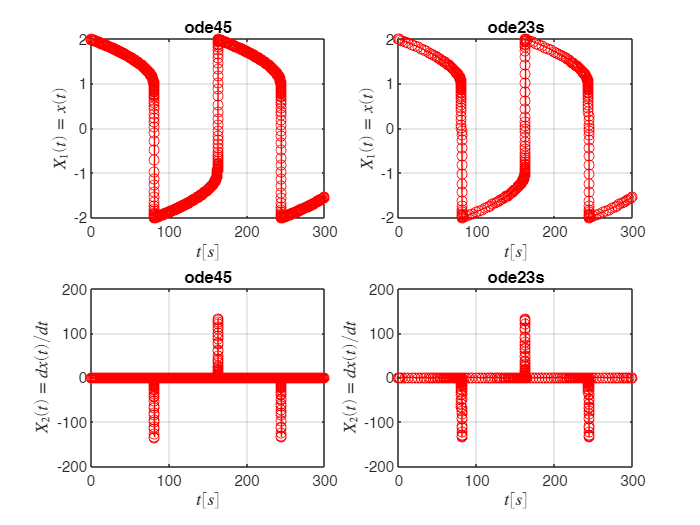

fig = figure('Color', 'white');

% ODE45
ax1 = axes(fig);
subplot(2, 2, 1, ax1);
plot(ax1, timeVect1, XMat1(:, 1), 'r-o');
xlabel(ax1, '$t [s]$', 'Interpreter', 'latex');
ylabel(ax1, '$X_1(t) = x(t)$', 'Interpreter', 'latex');
grid(ax1, 'on');
title('ode45');

ax2 = axes(fig);
subplot(2, 2, 3, ax2);
plot(ax2, timeVect1, XMat1(:, 2), 'r-o');
xlabel(ax2, '$t [s]$', 'Interpreter', 'latex');
ylabel(ax2, '$X_2(t) = dx(t)/dt$', 'Interpreter', 'latex');
grid(ax2, 'on');
title('ode45');

% ODE23S
ax3 = axes(fig);
subplot(2, 2, 2, ax3);
plot(ax3, timeVect2, XMat2(:, 1), 'r-o');
xlabel(ax3, '$t [s]$', 'Interpreter', 'latex');
ylabel(ax3, '$X_1(t) = x(t)$', 'Interpreter', 'latex');
grid(ax3, 'on');
title('ode23s');

ax4 = axes(fig);
subplot(2, 2, 4, ax4);
plot(ax4, timeVect2, XMat2(:, 2), 'r-o');
xlabel(ax4, '$t [s]$', 'Interpreter', 'latex');
ylabel(ax4, '$X_2(t) = dx(t)/dt$', 'Interpreter', 'latex');
grid(ax4, 'on');
title('ode23s');